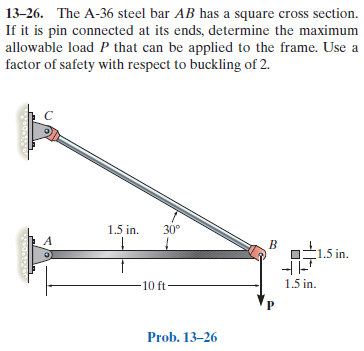

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-26P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-26P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = 30*u.deg;
Pvar = sym('P', 'positive');
[Pcr Pmax] = deal(default_struct('buckling', 'yield'));
jointA = [0 0]*u.ft;
jointB = [10 0]*u.ft;
jointC = [0 10*tan(theta)]*u.ft;

# member data

FS = 2;
E = rewrite(29e3*u.ksi, [u.kip u.ft]);
A = rewrite((1.5*u.in)^2, u.ft);
I = rewrite((1.5*u.in)^4/12, u.ft);
L = 10*u.ft;
sigma_yield = 36*u.ksi;
Evar = sym('E');
Avar = sym('A');

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Rc', {'Rcx' 'Rcy'}, jointC);
t = t.add('concentrated', 'Pb', [0 -Pvar], jointB);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fbc', jointB, jointC);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');
E = rewrite(E, u.ksi);
A = rewrite(A, u.in);
I = rewrite(I, u.in);

# joint displacements

ua

$$ua = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & -\frac{\sqrt{3}\,P}{6525}\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{vB} & -\frac{\sqrt{3}\,P\,\left(174000\,\mathrm{kip}+\sqrt{3}\,A\,\text{E}\right)}{6525\,A\,\text{E}}\,\frac{\mathrm{ft}}{\mathrm{kip}}\\ \mathrm{uC} & 0\\ \mathrm{vC} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m = ma.f.m %#ok<NASGU> 

$$ma\_f\_m = \left(\begin{array}{cc} \mathrm{Fab} & -\sqrt{3}\,P\\ \mathrm{Fbc} & 2\,P \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Ra} & \sqrt{3}\,P & 0 & 0\\ \mathrm{Rc} & -\sqrt{3}\,P & P & 0\\ \mathrm{Pb} & 0 & -P & 0 \end{array}\right)$$

ma_f_c = ma.f.c %#ok<NASGU> 

$$ma\_f\_c = \left(\begin{array}{cccc} \mathrm{Fab} & -\sqrt{3}\,P & 0 & 0\\ \mathrm{Fbc} & -\sqrt{3}\,P & P & 0 \end{array}\right)$$

la_f_m = la.f.m %#ok<NASGU> 

$$la\_f\_m = \left(\begin{array}{cc} \mathrm{Ra} & \sqrt{3}\,P\\ \mathrm{Rc} & 2\,P\\ \mathrm{Pb} & P \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & 10\,P\,\mathrm{ft} \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \mathrm{Rc} & 0 & 0 & 10\,P\,\mathrm{ft}\\ \mathrm{Pb} & 0 & 0 & -10\,P\,\mathrm{ft} \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & 10\,P\,\mathrm{ft} \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rc} & 10\,P\,\mathrm{ft}\\ \mathrm{Pb} & 10\,P\,\mathrm{ft} \end{array}\right)$$

# maximum load due to yield

Pcr.buckling = rewrite(sympi^2*E*I/L^2, u.kip);
Pcr_buckling = vpa(Pcr.buckling, 3) %#ok<NASGU> 

$$Pcr\_buckling = 8.39\,\mathrm{kip}$$

Pmax.buckling = solve(abs(ms.f.m.Fab) == Pcr.buckling/FS);
Pmax_buckling = vpa(Pmax.buckling, 3) %#ok<NASGU> 

$$Pmax\_buckling = 2.42\,\mathrm{kip}$$

# maximum load due to yield stress

Pcr.yield = rewrite(solve(sigma_yield == Pvar/A), u.kip);
Pcr_yield = Pcr.yield %#ok<NASGU> 

$$Pcr\_yield = 81\,\mathrm{kip}$$

Pmax.yield = solve(abs(ms.f.m.Fab) == Pcr.yield);
Pmax_yield = vpa(Pmax.yield, 4) %#ok<NASGU> 

$$Pmax\_yield = 46.77\,\mathrm{kip}$$

# clean up

new_assum = assumptions;
clear ma_f_m la_f_c ma_f_c la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;
clear Pcr_buckling Pmax_buckling;
clear Pcr_yield Pmax_yield;